# test drawing function

## generate matrix

rng(36,'twister');
A = unifrnd(0,1,[20,20]);
%A = rand(20,20);
den = 0.1;
A(A>den) = 1;
A(A<den) = 0;
%size(A)
%imshow(A)


## draw grid map

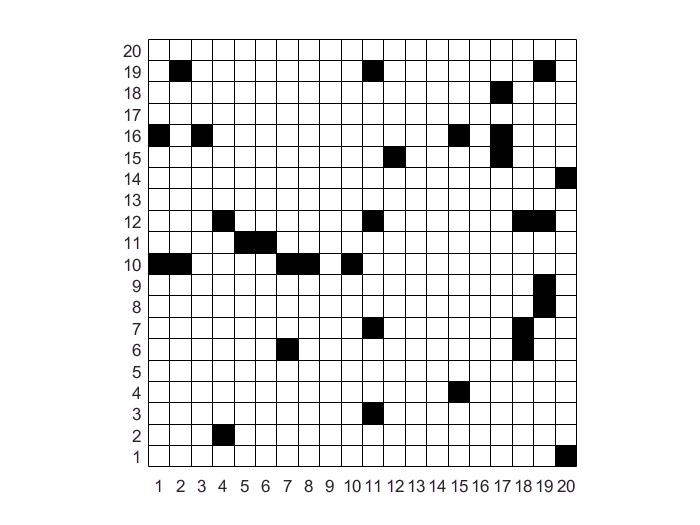

B = A;
%disp(A(end,end));
B(end+1,end+1) = 0;
%size(B)
%disp(B)

colormap([0 0 0;1 1 1]);  % color
pcolor(0.5:size(A,2)+0.5,0.5:size(A,1)+0.5,B); % grid color
% set coordinate
% gca: axes handler
% gcf: figure handler
% gco: mouse click handler
%get(gca)
set(gca,'XTick',1:size(A,2),'YTIck',1:size(A,1)); 
axis image xy;  % axis image is the same as axis equal except that the plot box fits tightly around the data.

## draw line

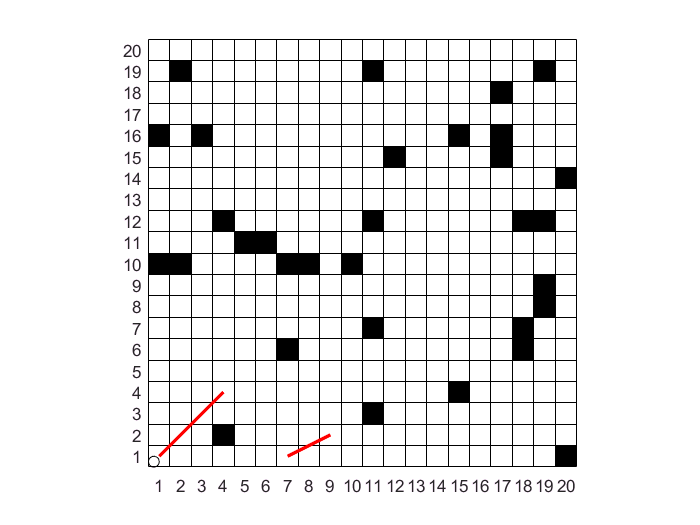

line([1,4],[1,4],'Color','r','LineWidth',2)
line([7,9],[1,2],'Color','r','LineWidth',2)
rectangle('Position',[0.5,0.5,0.5,0.5],'Curvature',1)

%plot(7,8,'rp')